**如何使用MATLAB进行图像处理**

说来惭愧，我实际很少使用matlab进行图象操作，只知道一些最基础的图象处理流程，包含读取、切割、旋转、转化为灰度图和保存图象，我把这些操作总结成一个小脚本方便你做参考。

P.S. 你需要Image Processing Toolbox来实现查看图片、保存图片的操作，不过没有也没关系，matlab会提醒你安装，按照要求操作就行

% 读取图像 
image = imread('C:\Users\96328\Image 7.tif');  
  
% 获取图像的分辨率  
[height, width, ~] = size(image);  
fprintf('分辨率: %dx%d\n', width, height);  

分辨率: 2048x2048


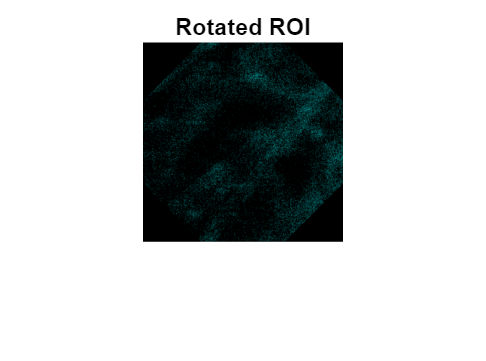

  
% 切割图像（Matlab和人类一样从1开始数数）  
x = 101;  
y = 101;  
w = 200;  
h = 200;  
roi = image(y:y+h-1, x:x+w-1, :);  
  
% 旋转切割后的图像（角度, 插值方法, 边界选项）    
rotated_roi = imrotate(roi, 45, 'bilinear', 'crop');  
  
% 显示旋转后的切割图像  
imshow(rotated_roi);  
title('Rotated ROI');


% 将图象转化为灰度图
GreyImage = rgb2gray(image);

% 保存图象
imwrite(GreyImage, 'C:\Users\96328\GreyImage.jpg');  